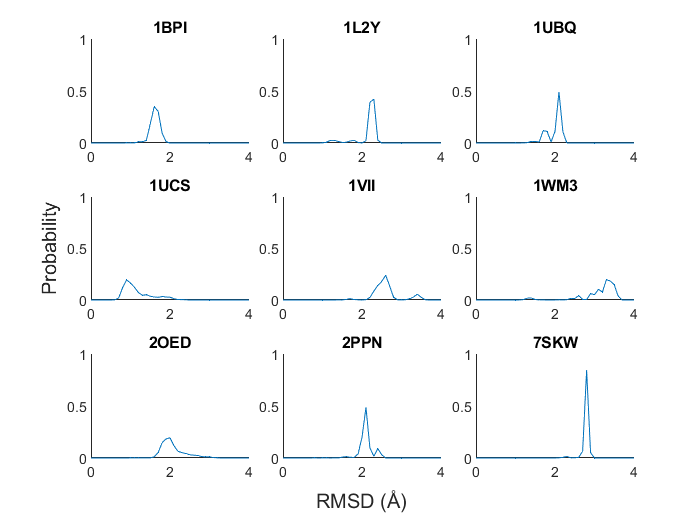

% Plot histograms of protein RMSD distributions
% Probability distributions were created in Excel 
% (see files/proteinRMSDdistributions.xlsx)

% Read in probability distributions file
fullProbBins = readtable("files/proteinRMSDdistributions_probabilities.csv");
Ang = char(197);

t1=tiledlayout(3,3);
nexttile
plotDistributions(fullProbBins.Bins, fullProbBins.p1bpi, '1BPI');
nexttile
plotDistributions(fullProbBins.Bins, fullProbBins.p1l2y, '1L2Y');
nexttile
plotDistributions(fullProbBins.Bins, fullProbBins.p1ubq, '1UBQ');
nexttile
plotDistributions(fullProbBins.Bins, fullProbBins.p1ucs, '1UCS');
nexttile
plotDistributions(fullProbBins.Bins, fullProbBins.p1vii, '1VII');
nexttile
plotDistributions(fullProbBins.Bins, fullProbBins.p1wm3, '1WM3');
nexttile
plotDistributions(fullProbBins.Bins, fullProbBins.p2oed, '2OED');
nexttile
plotDistributions(fullProbBins.Bins, fullProbBins.p2ppn, '2PPN');
nexttile
plotDistributions(fullProbBins.Bins, fullProbBins.p7skw, '7SKW');
t1.TileSpacing='compact';
xlabel(t1,['RMSD (',Ang,')']);
ylabel(t1,'Probability');

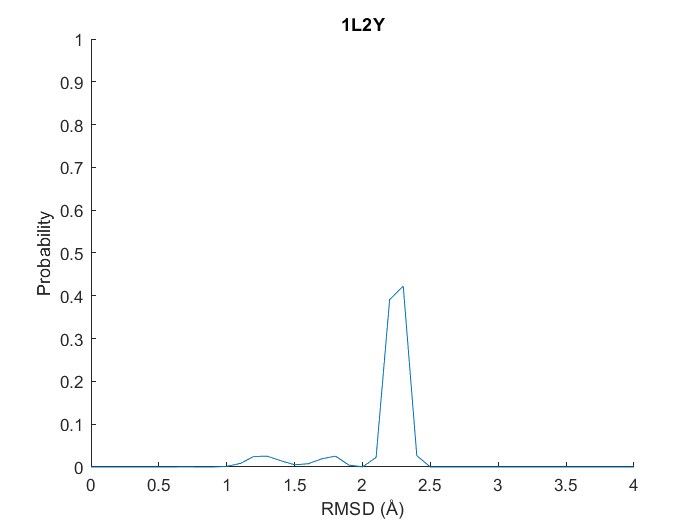


figure
plotDistributions(fullProbBins.Bins, fullProbBins.p1l2y, '1L2Y')
xlabel(['RMSD (',Ang,')']);
ylabel('Probability')

function plotDistributions(bins,prot,protname)
% Plot histogram of RMSD distribution
  line(bins,prot)
  hold on
  title(protname)
  ylim([0,1.0]);
  hold off
end